disp("Independent work 08 - interpolation 03.")

Independent work 08 - interpolation 03.


disp("Question 01.")

Question 01.



% Given data points
x = [3, 4, 5, 6]

x =      3     4     5     6


y = [1.8353, 1.9633, 1.9453, 2.2797]

y =     1.8353    1.9633    1.9453    2.2797



% Number of intervals
n = length(x) - 1;

% Step 1: Compute h (interval lengths)
h = diff(x);  % h(i) = x(i+1) - x(i)

% Step 2: Create the matrix A and vector B for the system A * c = B
A = zeros(n+1, n+1);
B = zeros(n+1, 1);

% Step 3: Set up the system of equations
disp('System of equations: A * c = B')

System of equations: A * c = B



% First row (boundary condition: c1 = 0)
A(1, 1) = 1;

% Intermediate rows (for cubic spline conditions)
for i = 2:n
    A(i, i-1) = h(i-1);
    A(i, i) = 2 * (h(i-1) + h(i));
    A(i, i+1) = h(i);
    B(i) = 3 * ((y(i+1) - y(i)) / h(i) - (y(i) - y(i-1)) / h(i-1));
end

% Last row (boundary condition: cn = 0)
A(n+1, n) = h(n);
A(n+1, n+1) = 1;

% Display the system of equations in matrix form
disp('Matrix A:')

Matrix A:


disp(A)

     1     0     0     0
     1     4     1     0
     0     1     4     1
     0     0     1     1




disp('Vector B:')

Vector B:


disp(B)

         0
   -0.4380
    1.0572
         0




% Display the system of equations in string form
disp('The system of equations for c (second derivatives):')

The system of equations for c (second derivatives):


for i = 2:n
    fprintf('Equation %d: %.4f * c(%d) + %.4f * c(%d) = %.4f\n', ...
            i, A(i,i-1), i-1, A(i,i), i, B(i));
end

Equation 2: 1.0000 * c(1) + 4.0000 * c(2) = -0.4380
Equation 3: 1.0000 * c(2) + 4.0000 * c(3) = 1.0572



% Step 4: Solve the system using matrix inversion (X = A^(-1) * B)
c = inv(A) * B;

% Display the second derivatives (c)
disp('Second derivatives at the interpolation points (c):')

Second derivatives at the interpolation points (c):


disp(c)

         0
   -0.2156
    0.4243
   -0.4243




% Step 5: Compute other coefficients b, d, and a

% Initialize arrays for b, d, and a
b = zeros(n, 1);
d = zeros(n, 1);
a = y(1:n);

% Compute b and d coefficients
for i = 1:n
    b(i) = (y(i+1) - y(i)) / h(i) - h(i) * (2 * c(i) + c(i+1)) / 3;
    d(i) = (c(i+1) - c(i)) / (3 * h(i));
end

% Display the coefficients a, b, c, and d
disp('Spline coefficients:')

Spline coefficients:


disp('a = ')

a = 


disp(a)

    1.8353    1.9633    1.9453



disp('b = ')

b = 


disp(b)

    0.1999
   -0.0157
    0.1930



disp('c = ')

c = 


disp(c)

         0
   -0.2156
    0.4243
   -0.4243



disp('d = ')

d = 


disp(d)

   -0.0719
    0.2133
   -0.2828




% Step 6: Display the spline equations for each interval
disp('Spline equations for each interval:')

Spline equations for each interval:


for i = 1:n
    fprintf('Interval %d: P%d(x) = %.4f + %.4f*(x - %.4f) + %.4f*(x - %.4f)^2 + %.4f*(x - %.4f)^3\n', ...
            i, i, a(i), b(i), x(i), c(i), x(i), d(i), x(i));
end

Interval 1: P1(x) = 1.8353 + 0.1999*(x - 3.0000) + 0.0000*(x - 3.0000)^2 + -0.0719*(x - 3.0000)^3
Interval 2: P2(x) = 1.9633 + -0.0157*(x - 4.0000) + -0.2156*(x - 4.0000)^2 + 0.2133*(x - 4.0000)^3
Interval 3: P3(x) = 1.9453 + 0.1930*(x - 5.0000) + 0.4243*(x - 5.0000)^2 + -0.2828*(x - 5.0000)^3


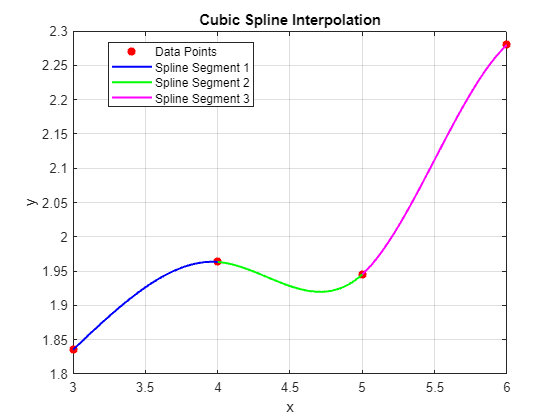


% Define the spline polynomial function
P = @(i, xx) a(i) + b(i) * (xx - x(i)) + c(i) * (xx - x(i)).^2 + d(i) * (xx - x(i)).^3;

% Step 7: Plotting the spline interpolation with different colors
plot(x, y, 'r*', 'LineWidth', 2, 'DisplayName', 'Original Points')
hold on

% Plot interpolation polynomial with different colors for each section
colors = ['b', 'g', 'm', 'c'];
for i = 1:n
    xx = linspace(x(i), x(i+1), 100);
    yy = P(i, xx);
    plot(xx, yy, 'Color', colors(i), 'LineWidth', 1.5)
end

% Customize plot
title('Cubic Spline Interpolation with Multi-Color Sections')
xlabel('x')
ylabel('y')
title('Cubic Spline Interpolation');
legend('Data Points', 'Spline Segment 1', 'Spline Segment 2', 'Spline Segment 3', 'Location', 'Best');
grid on
legend show
hold off